## Newton method

We have to be sure that the initial assumptions are satisfied, i.e. that the f' is well defined and not null in the domain.

f = @(x) sin(x).*((1 - x).^2);

a = -0.5;
b = 1.5;

x = linspace(a, b, 1000);

figure();
plot(x, f(x));
grid on;
hold on;

Let's check also the first derivative:

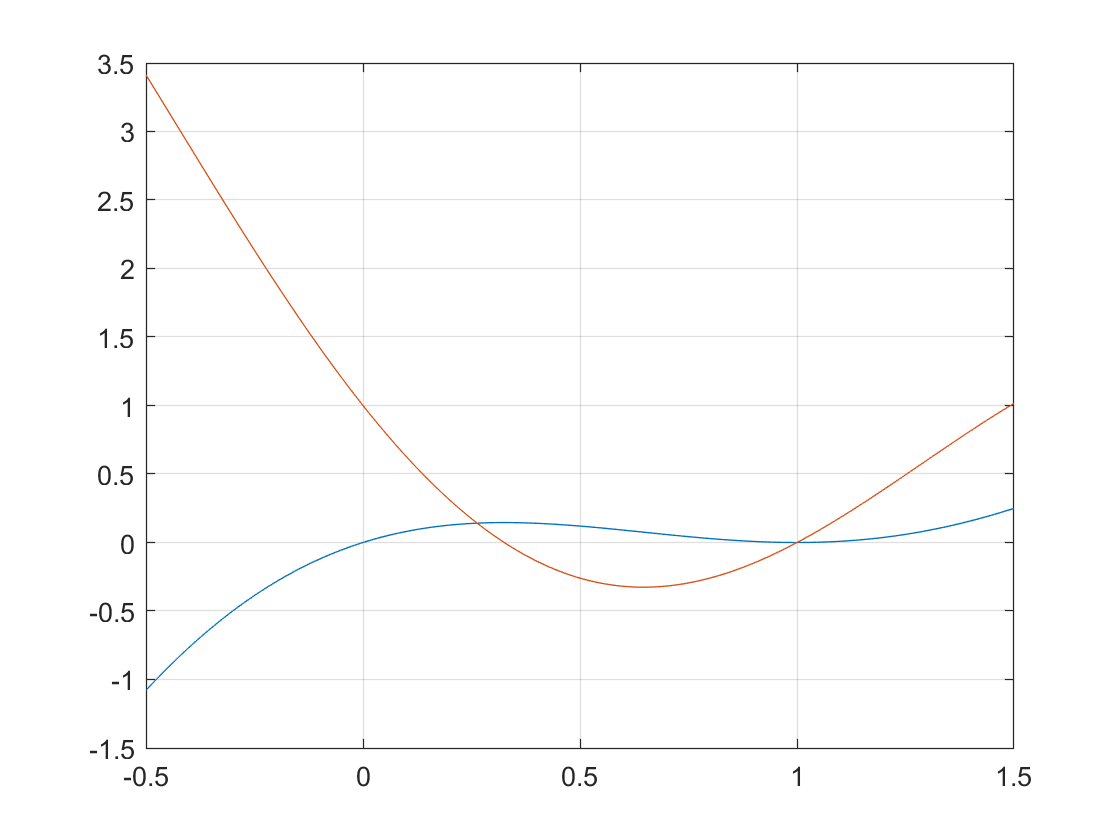

df = @(x) cos(x).*(1 - x).^2 - 2*sin(x).*(1-x);

plot(x, df(x));
hold off;

The Newton method has a local convergence, so if we are far from the zero we will converge to another point.

Call the newton method:

Nmax = 200;
tol = 1e-6;
x0 = 0.3;

[x, x_iter] = newton(f, df, x0, tol, Nmax)

x =   -4.3720e-23


x_iter =    3.0000e-01  -2.3625e+00  -4.7553e+00  -1.4718e+00  -3.7100e-01  -1.2282e-01  -2.1630e-02  -8.7556e-04  -1.5290e-06  -4.6755e-12  -4.3720e-23



display(abs(x));

   4.3720e-23



Functions:

function [x, x_iter] = newton(f, df, x0, tol, Nmax)
    % Nmax since we don't know a priori if with the passed
    % tol we will reach a convergence

    x_iter(1) = x0;
    
    for k = 2:Nmax
        
        % Check if the derivative is zero or simil-zero
        if abs(df(x_iter(k-1))) < 1e-8
            break;
        end
        
        x_iter(k) = x_iter(k-1) - (f(x_iter(k-1)) / df(x_iter(k-1)));
    
        if abs(x_iter(k) - x_iter(k-1)) < tol
            break;
        end
    end
    
    x = x_iter(end);
end